# Exercises 7.1

3. Determine the shape functions for a 1D isoparametric element with four and five nodes by calculating the polynomialcoefficients using a system of equations.  Later, compare the results with the shape functions obtained using Lagrangepolynomials. Plot the obtained shape functions.

## 5 Nós

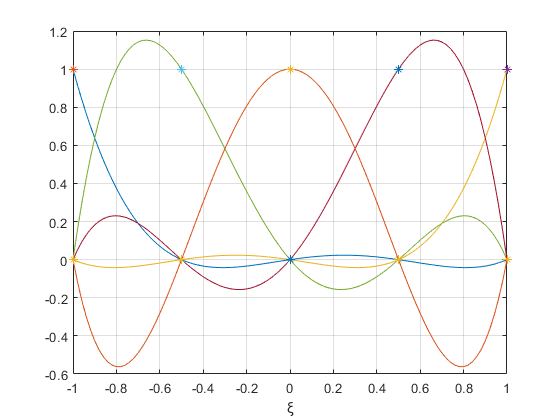

n = 101;
xi = linspace (-1, 1, n);      
u1 = [1.00 0.00 0.00 0.00 0.00]';
u2 = [0.00 1.00 0.00 0.00 0.00]';               
u3 = [0.00 0.00 1.00 0.00 0.00]';               
u4 = [0.00 0.00 0.00 1.00 0.00]';               
u5 = [0.00 0.00 0.00 0.00 1.00]';               

for i = 1:n
    N5 = shape_form_1d_5n(xi(i));
    U1(i, 1) =  N5 * u1;

    N5 = shape_form_1d_5n(xi(i));
    U2(i, 1) =  N5 * u2;

    N5 = shape_form_1d_5n(xi(i));
    U3(i, 1) =  N5 * u3;

    N5 = shape_form_1d_5n(xi(i));
    U4(i, 1) =  N5 * u4;

    N5 = shape_form_1d_5n(xi(i));
    U5(i, 1) =  N5 * u5;
end

figure
plot(xi,U1,[-1,1,-1/2,1/2,0],u1,'*')
grid;
xlabel ("ξ");
hold on
plot(xi,U2,[-1,1,-1/2,1/2,0],u2,'*')
hold on
plot(xi,U3,[-1,1,-1/2,1/2,0],u3,'*')
hold on
plot(xi,U4,[-1,1,-1/2,1/2,0],u4,'*')
hold on
plot(xi,U5,[-1,1,-1/2,1/2,0],u5,'*')
hold on

clear all

## 4 Nós

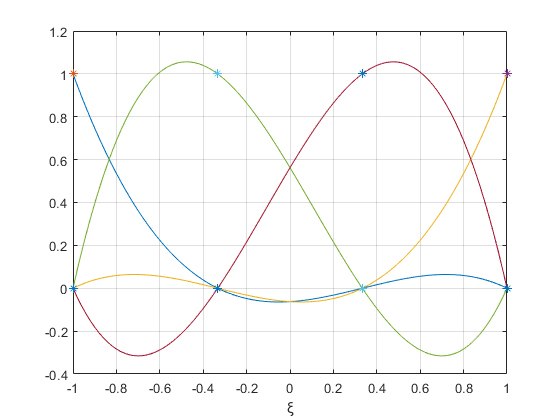

n = 101;
xi = linspace (-1, 1, n);      
u1 = [1.00 0.00 0.00 0.00]';
u2 = [0.00 1.00 0.00 0.00]';               
u3 = [0.00 0.00 1.00 0.00]';               
u4 = [0.00 0.00 0.00 1.00]';               

for i = 1:n
    N4 = shape_form_1d_4n(xi(i));
    U1(i, 1) =  N4 * u1;

    N4 = shape_form_1d_4n(xi(i));
    U2(i, 1) =  N4 * u2;

    N4 = shape_form_1d_4n(xi(i));
    U3(i, 1) =  N4 * u3;

    N4 = shape_form_1d_4n(xi(i));
    U4(i, 1) =  N4 * u4;
end

figure
plot(xi,U1,[-1,1,-1/3,1/3],u1,'*')
grid;
xlabel ("ξ");
hold on
plot(xi,U2,[-1,1,-1/3,1/3],u2,'*')
hold on
plot(xi,U3,[-1,1,-1/3,1/3],u3,'*')
hold on
plot(xi,U4,[-1,1,-1/3,1/3],u4,'*')
hold on

function N5 = shape_form_1d_5n(xi)
N5 = [
1/6*(    xi -  xi^2 - 4*xi^3 + 4*xi^4);   % N1    
1/6*(-   xi -  xi^2 + 4*xi^3 + 4*xi^4);   % N2
1/3*(-4*xi + 8*xi^2 + 4*xi^3 - 8*xi^4);   % N3
1/3*( 4*xi + 8*xi^2 - 4*xi^3 - 8*xi^4);   % N4
(1         - 5*xi^2          + 4*xi^4)    % N5
]';           
end

function N4 = shape_form_1d_4n(xi)
N4 = [
1/16*(-1 +    xi + 9*xi^2 -  9*xi^3);    % N1    
1/16*(-1 -    xi + 9*xi^2 +  9*xi^3);    % N2
1/16*( 9 - 27*xi - 9*xi^2 + 27*xi^3);    % N3
1/16*( 9 + 27*xi - 9*xi^2 - 27*xi^3)     % N4
]';
         
end